# Second-Order Lab: Second-Order Linear DEs in MATLAB

In this lab, you will learn how to use `iode` to plot solutions of second-order ODEs. You will also learn to classify the behaviour of different types of solutions.

Moreover, you will write your own Second-Order ODE system solver, and compare its results to those of `iode`.

Opening the m-file lab5.m in the MATLAB editor, step through each part using cell mode to see the results.

There are seven (7) exercises in this lab that are to be handed in on the due date of the lab.

## Student Information

## Exercise 1

a) see attached image

b) All solutions decay while oscillating, except for the trivial solution y = 0

c) y(t) = exp(-t/2)*(C1*cos(2t)+C2*sin(2t))

This is verified by the analytical solution, which is a product of the exponential function with a negative exponent and sinusoidal terms. The function will oscillate about x=0 but due to the exp(-t/2) term and the negative exponent, the function will decay and approach zero as t grows for all initial values C1 and C2.

## Exercise 2

a) see attached image

b) Almost all solutions grow, except the trivial solution y = 0 and when C1 = 0.

c) y(t) = C1*exp((-sqrt(3)+2)*t/2) + C2*exp((-sqrt(3)-2)*t/2)

The analytical solution has a positive exponential term exp((-sqrt(3)+2)*t/2). This means that all solutions will eventually grow to +/-infinity, depending on the sign of C1, given large t. Note the negative exponent term, (-sqrt(3)-2)t/2, will decay to 0 so it becomes insigificant with larges positive t's.

However, one case where the solutions decay instead of grow is when C1=0. In this case the positive exponential term is eliminated, leaving the negative exponential term, resulting in decaying solutions for all C2.

## Exercise 3

a) see attached image

b) All solutions decay to 0 without oscillating, except for the trivial solution y = 0

c) y(t) = exp((-sqrt(3)+sqrt(2))t/2)) + C2*exp((-sqrt(3)-sqrt(2))t/2)

The analytical solution is a sum of exponentials, with both exponents negative. As t grows, both exponents approach 0, so the solution decays without oscillating (there is no sinusoidal term so no oscillations).

## Exercise 4

a)

C = [1, 2, 6, 2, 5];
roots(C)

ans =   -1.0000 + 2.0000i
  -1.0000 - 2.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i


b)

The four roots to the equation are -1+2i, -1-2i, i, -i. Therefore the general solution is exp(-t)(Acos(2t)+Bsin(2t))+Ccos(t)+Dsin(t), where A,B,C, and D are arbitrary constants. Due to the sin and cos terms without the exponential (the C and D terms), the solution will not decay for large t. The first two terms which have exp(-t) as a factor will decay to zero, but the last two terms will conintue to oscillate. Therefore, for large t, the solutions will oscillate about y=0 without decay.

However, with the special case where C=D=0 and either A and B, or both, is nonzero, the solution will decay to zero since there is no longer terms without an exponential decay term, exp(-t), attached.

## Exercise 5

(a) `0 < r1 < r2`

(b) `r1 < 0 < r2`

(c) `r1 < r2 < 0`

(d) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha < 0`

(e) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha = 0`

(f) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha > 0`

`a) all solutions grow without oscillating`

`b) most solutions grow without osicllating, expect when the constant term attached to the r2 exponential is 0, in which case solutions decay without osicllating`

`c) all solutions decay without oscillating`

`d) all solutions decay while oscillating`

`e) all solutions oscillate without growth or decay (sinusoids)`

`f) all solutions grow while oscillating`

`The exception for all above classification is the trivial solution y=0, in which case the solution is constant with no growth, decay, or oscillations.`

## Exercise 6

See DE2_wuqingy6.m for the solver's code.

## Exercise 7

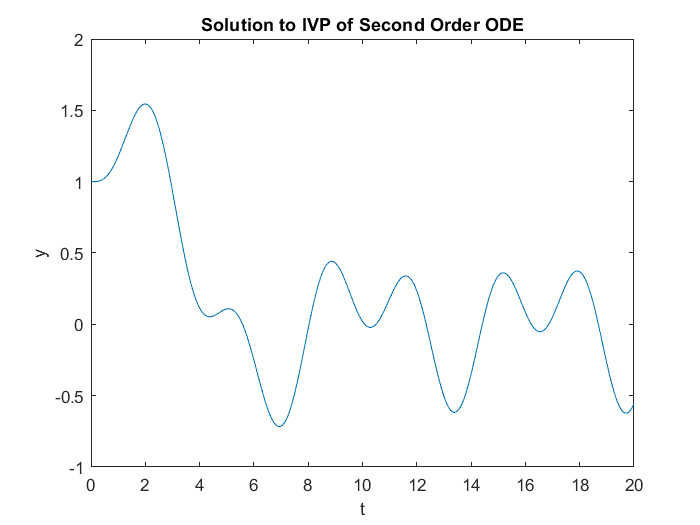

g = @(t) sin(2*t);
p = @(t) exp(-t/5);
q = @(t) 1-exp(-t/5);
y0 = 1;
y1 = 0;
t0 = 0;
tN = 20;
h = 0.05;
[t,y] = DE2_wuqingy6(t0,tN,y0,y1,h, p, q, g);

plot(t,y);
xlabel("t");
ylabel("y");
title("Solution to IVP of Second Order ODE");

There are very small differences between my DE solver (using finite differences) and iode's second order solver (using Euler's method) for the same time steps. For the attached screenshot, the time step for both was set to 0.05.

Note the solutions differ slightly whenever there is a large derivative change in the graph, i.e., near the maximum and minimum values of the graph.

In the attached image, the blue graph is the approximation produced by DE2_wuqingy6, while the red graph is the approximation produced by iode.